# ME 507 - Inverted Pendulum Control

**Author: Jake Vormbaum**

**Date Created: 10/03/2023**

**Date Modified: 10/04/2023**

**Description:** 

- **pendulum_script.mlx**: This script contains the inputs as well as plots the results

- **pendulum_model.slx:** This model contains the block diagram of the control loop

clc;
clear;
close;

## Define the Parameters

### Physical

mc = 0.15;          % Mass of the cart
mp = 0.30;          % Mass of the pendulum
g = 9.81;           % Earth gravity
L = 0.25;           % Length of the pendulum
d1 = 1e-2;          % Damping of the cart displacement
d2 = 1e-2;          % Damping in the joint
b_rolling = 0.5;    % Rolling resistance
b_pitching = 1.5;   % Pitch damping

### Motors

stall_T_datasheet = 7.0;                % Motor stall torque [kgf-cm]
stall_T = 2*stall_T_datasheet*(g/100)   % Motor stall torque [N-m]

stall_T = 1.3734

## Define the Matrices

A = [0,     0,                  1,          0
     0,     0,                  0,          1
     0,     g*mp/mc             -d1/mc      d2/(L*mc)
     0,     g*(mc+mp)/(L*mc)    -d1/(L*mc)  -d2*(mc+mp)/(L^2*mc*mp)];
B = [0
     0
     1/mc
     1/(L*mc)];

## Output

C = [1, 0, 0, 0
     0, 1, 0, 0
     0, 0, 1, 0
     0, 0, 0, 1];
D = 0;

## Build the System

sys = ss(A,B,C,D);
x_0 = [0;    0*pi/180;   0;  0];

## Targets and Disturbance

target_angle = 0.0*(pi/180);        % radians
period = 20;                        % s
pulse_width = 1;                    %
disturbance = 0.75;                 % N-m

## Controller

K_p_pitch = 15.0;   % Proportional gain
K_i_pitch = 5.0;    % Integral gain

## Run the Model

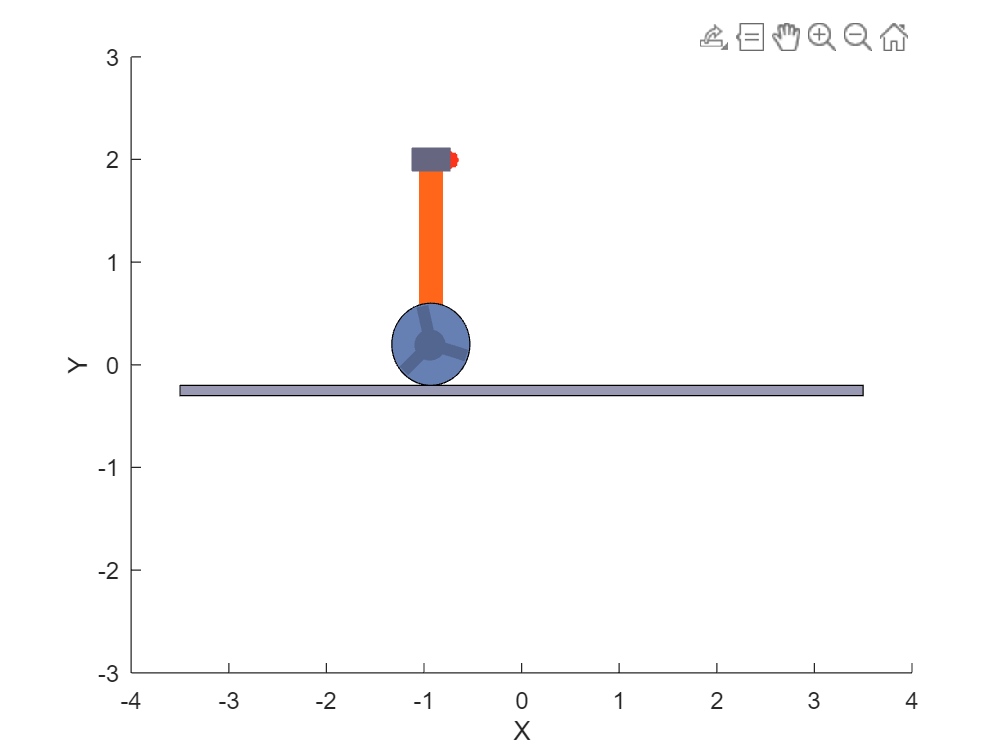

t_stop = 25;
simout = sim("pendulum_model_PI.slx", t_stop);

## Plot Data

### Load Data

load output;

### Read Data

x = simout.x(:,1);
theta = simout.x(:,2)*180/pi;
x_dot = simout.x(:,3);
theta_dot = simout.x(:,4)*60/(2*pi);
theta_ref = out.Data(:,5)*180/pi;
t = out.Time;
torque = simout.u;

### Plot Data

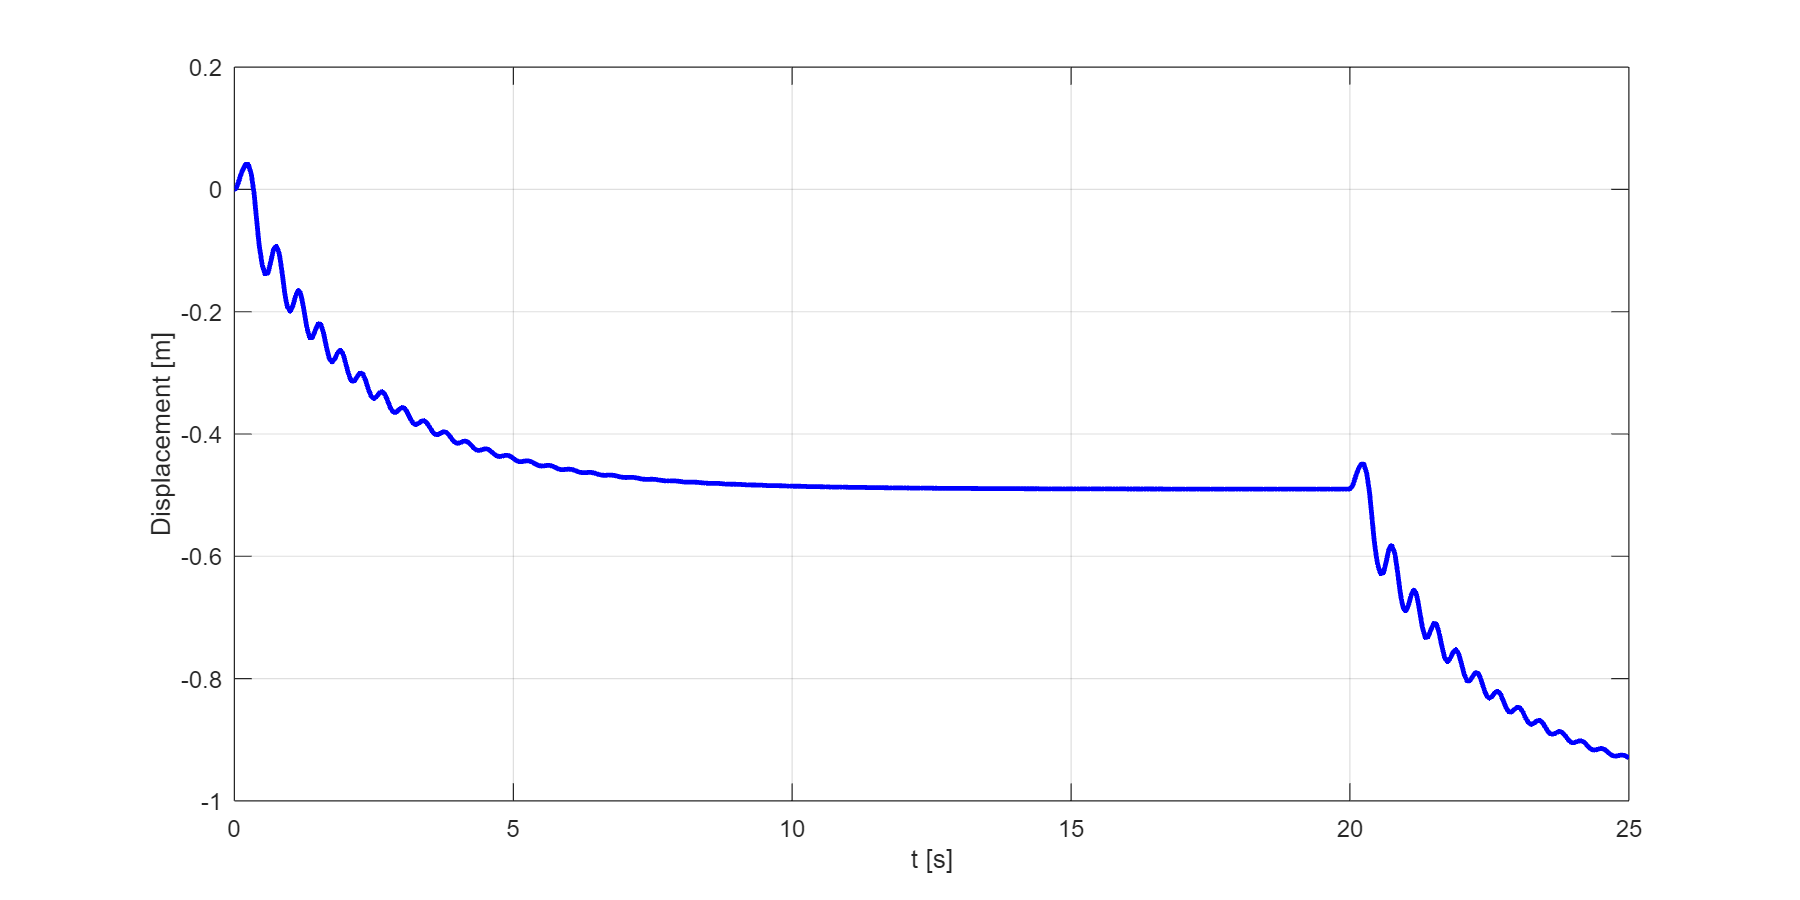

figure('Position',[0 0 1000 500]);
plot(t,x,'b','LineWidth',2); grid on
ylabel('Displacement [m]')
xlabel('t [s]')

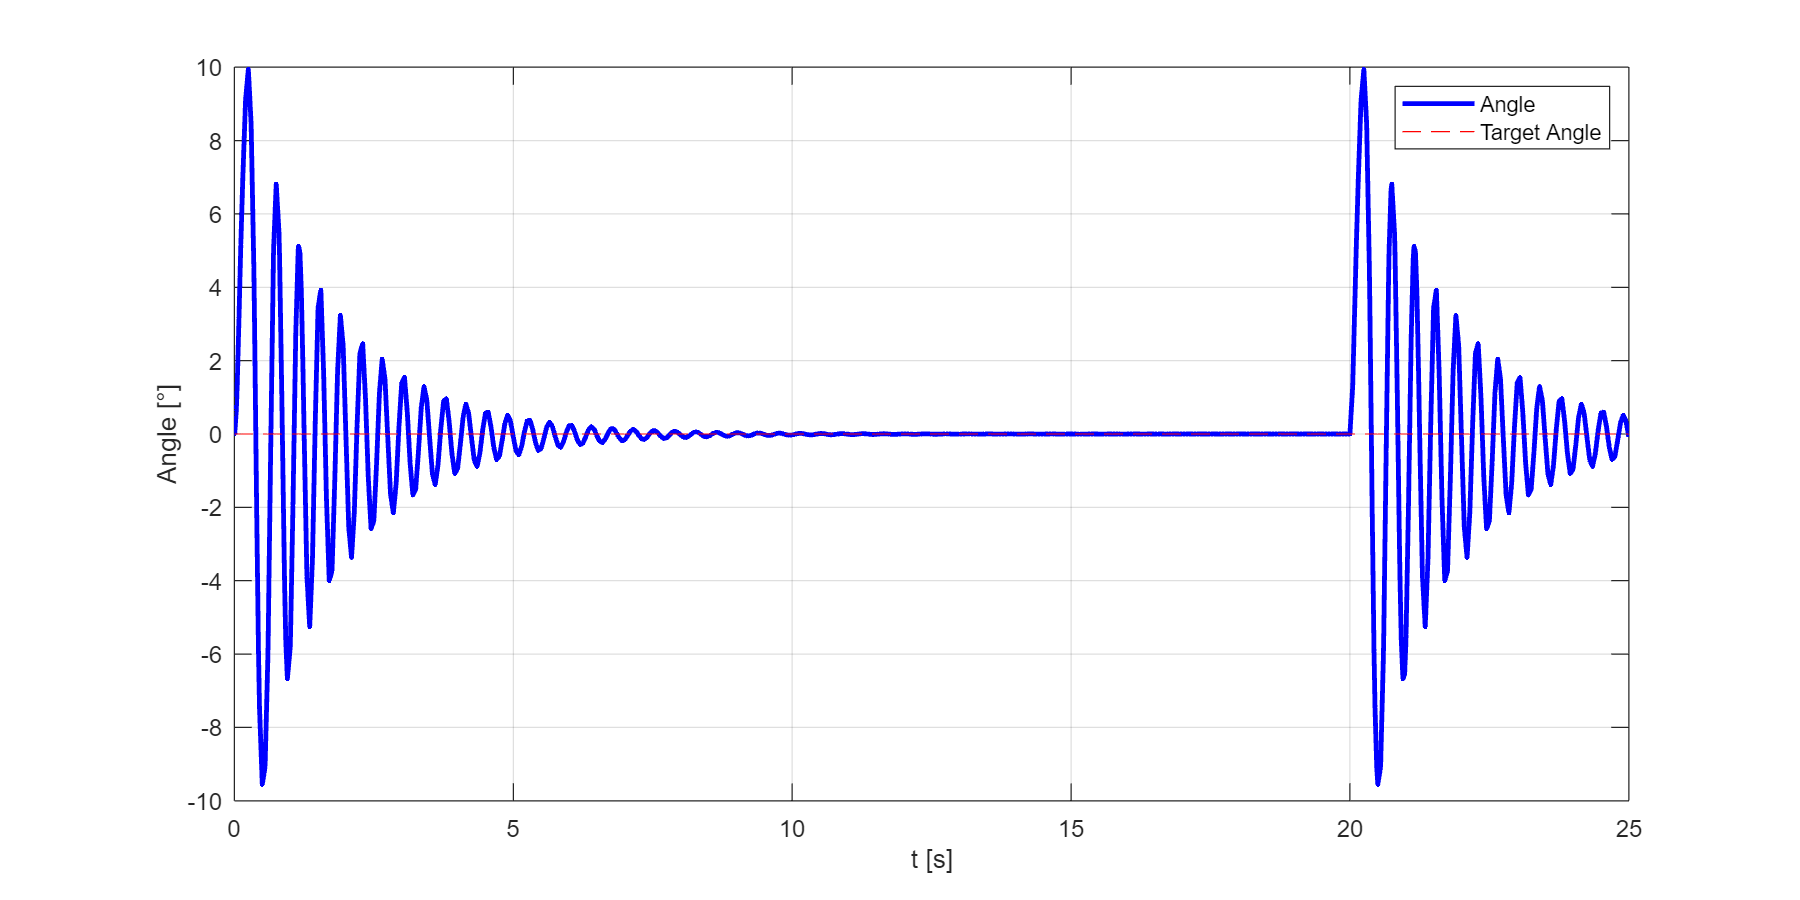

figure('Position',[0 0 1000 500]);
plot(t,theta,'b','LineWidth',2); grid on
hold on
plot(t,theta_ref,'r--')
hold off
ylabel('Angle [°]')
xlabel('t [s]')
legend('Angle','Target Angle')

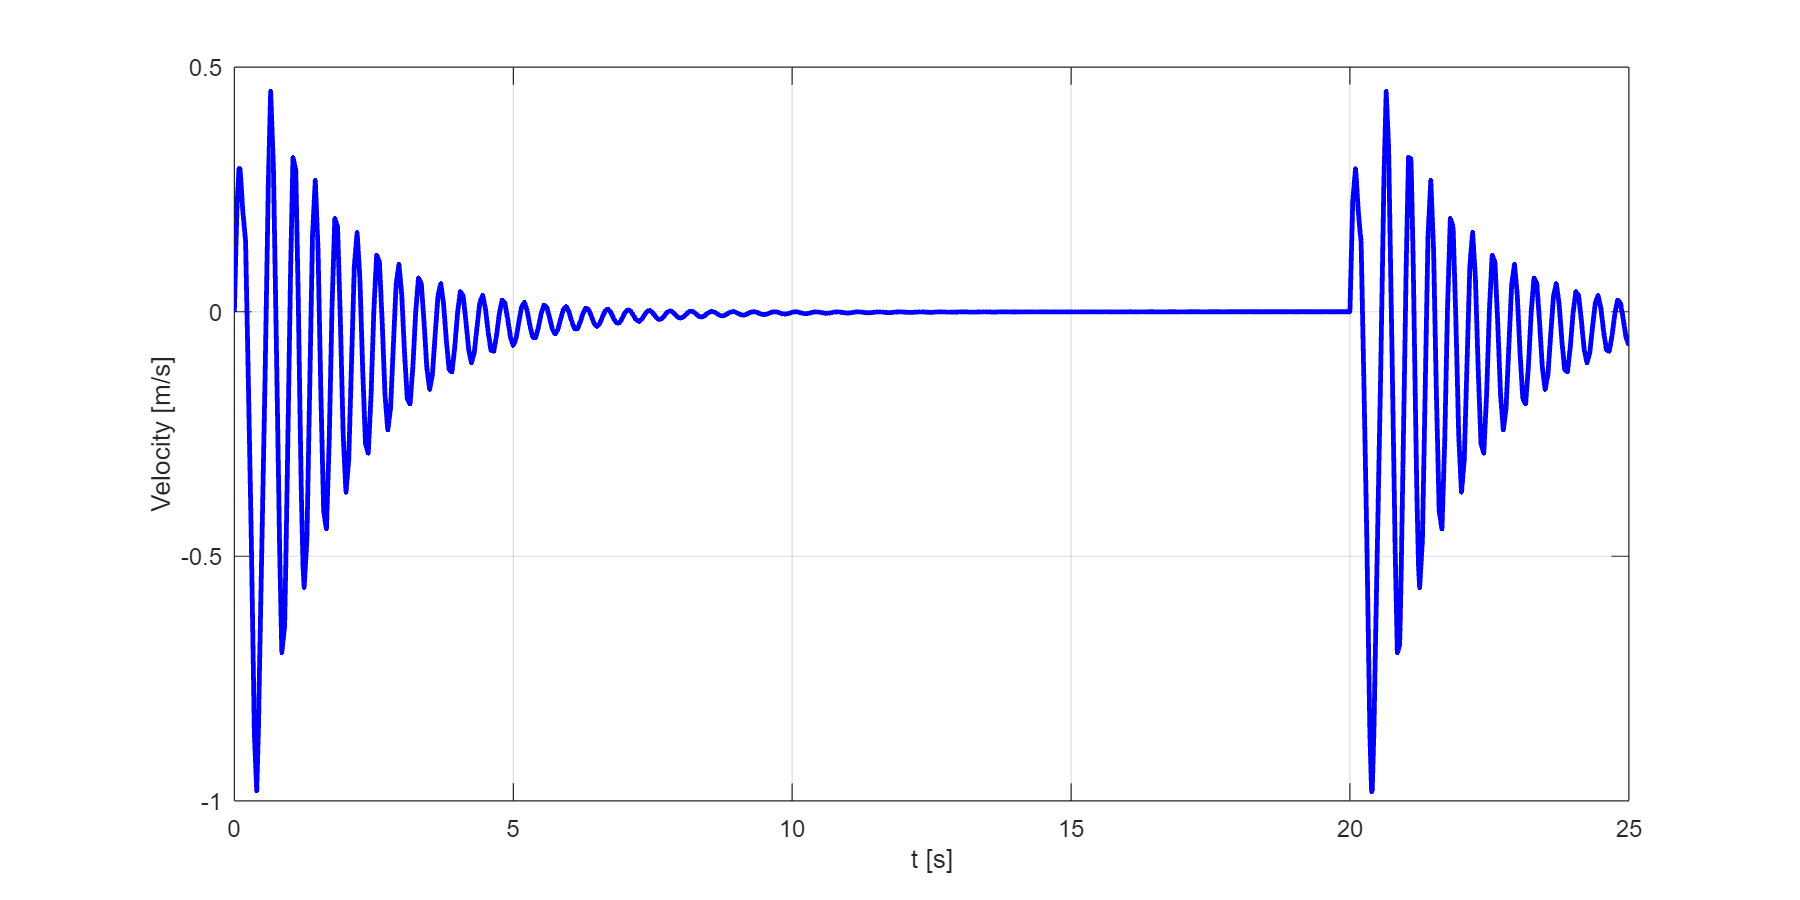

figure('Position',[0 0 1000 500]);
plot(t,x_dot,'b','LineWidth',2); grid on
ylabel('Velocity [m/s]')
xlabel('t [s]')

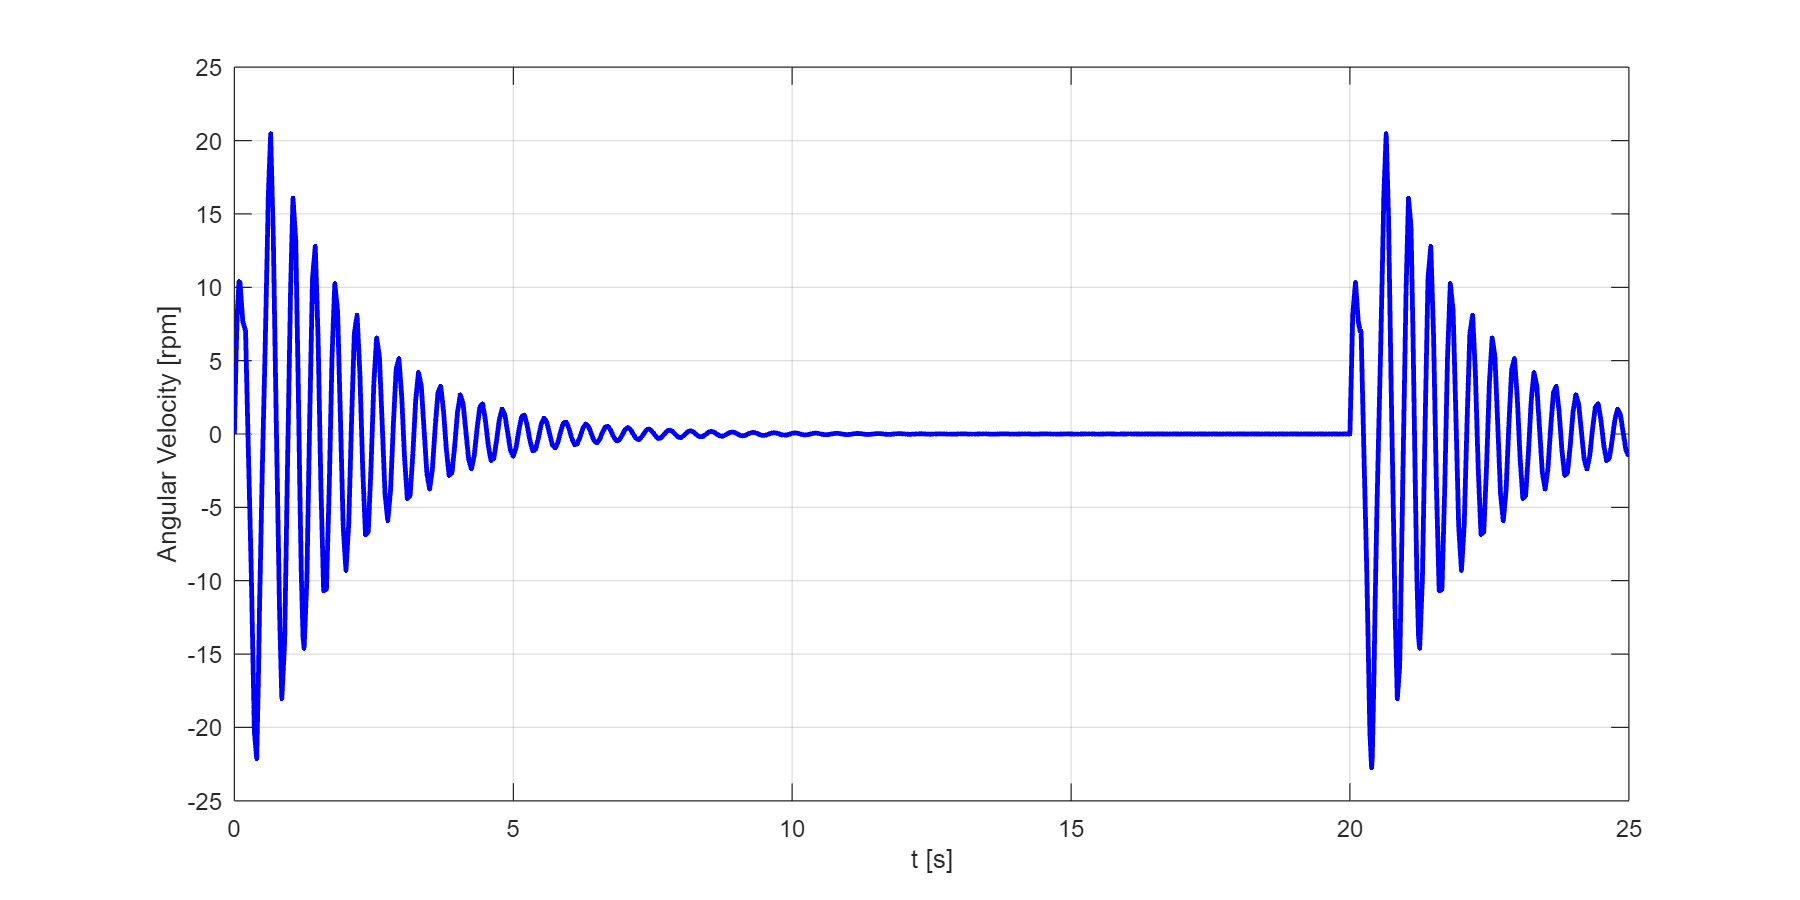

figure('Position',[0 0 1000 500]);
plot(t,theta_dot,'b','LineWidth',2); grid on
ylabel('Angular Velocity [rpm]')
xlabel('t [s]')

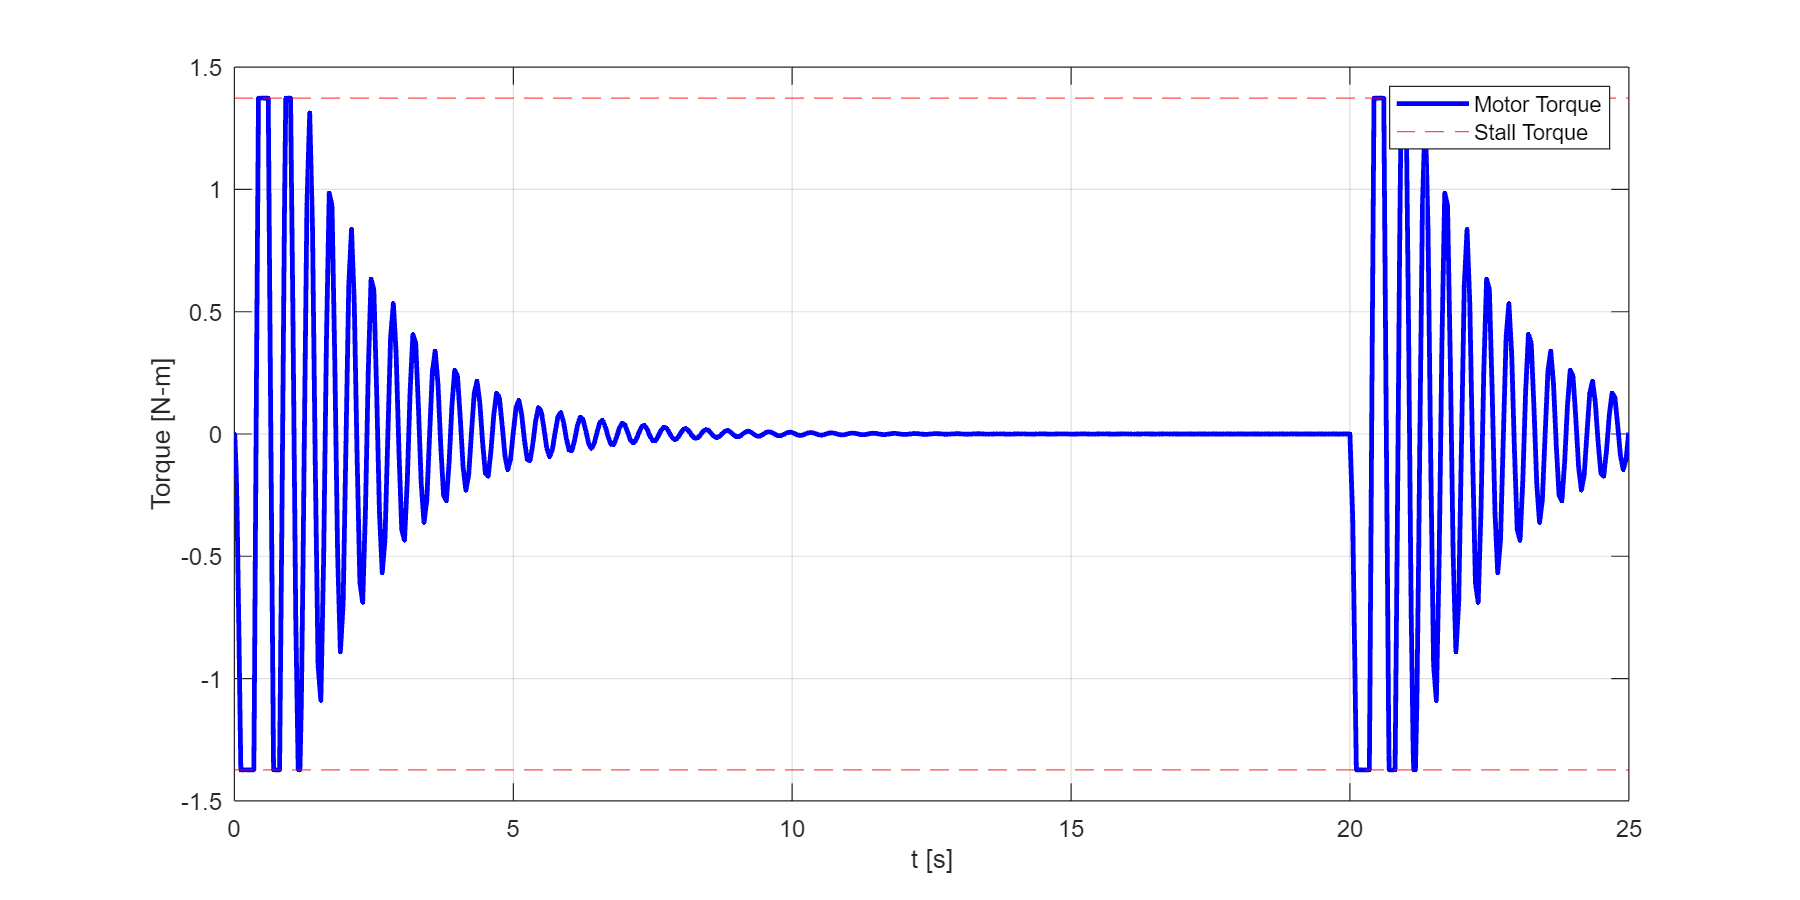


figure('Position',[0 0 1000 500]);
plot(t,torque,'b','LineWidth',2); grid on
hold on
yline(stall_T,'r--')
yline(-stall_T,'r--')
hold off
ylabel('Torque [N-m]')
xlabel('t [s]')
legend('Motor Torque','Stall Torque')

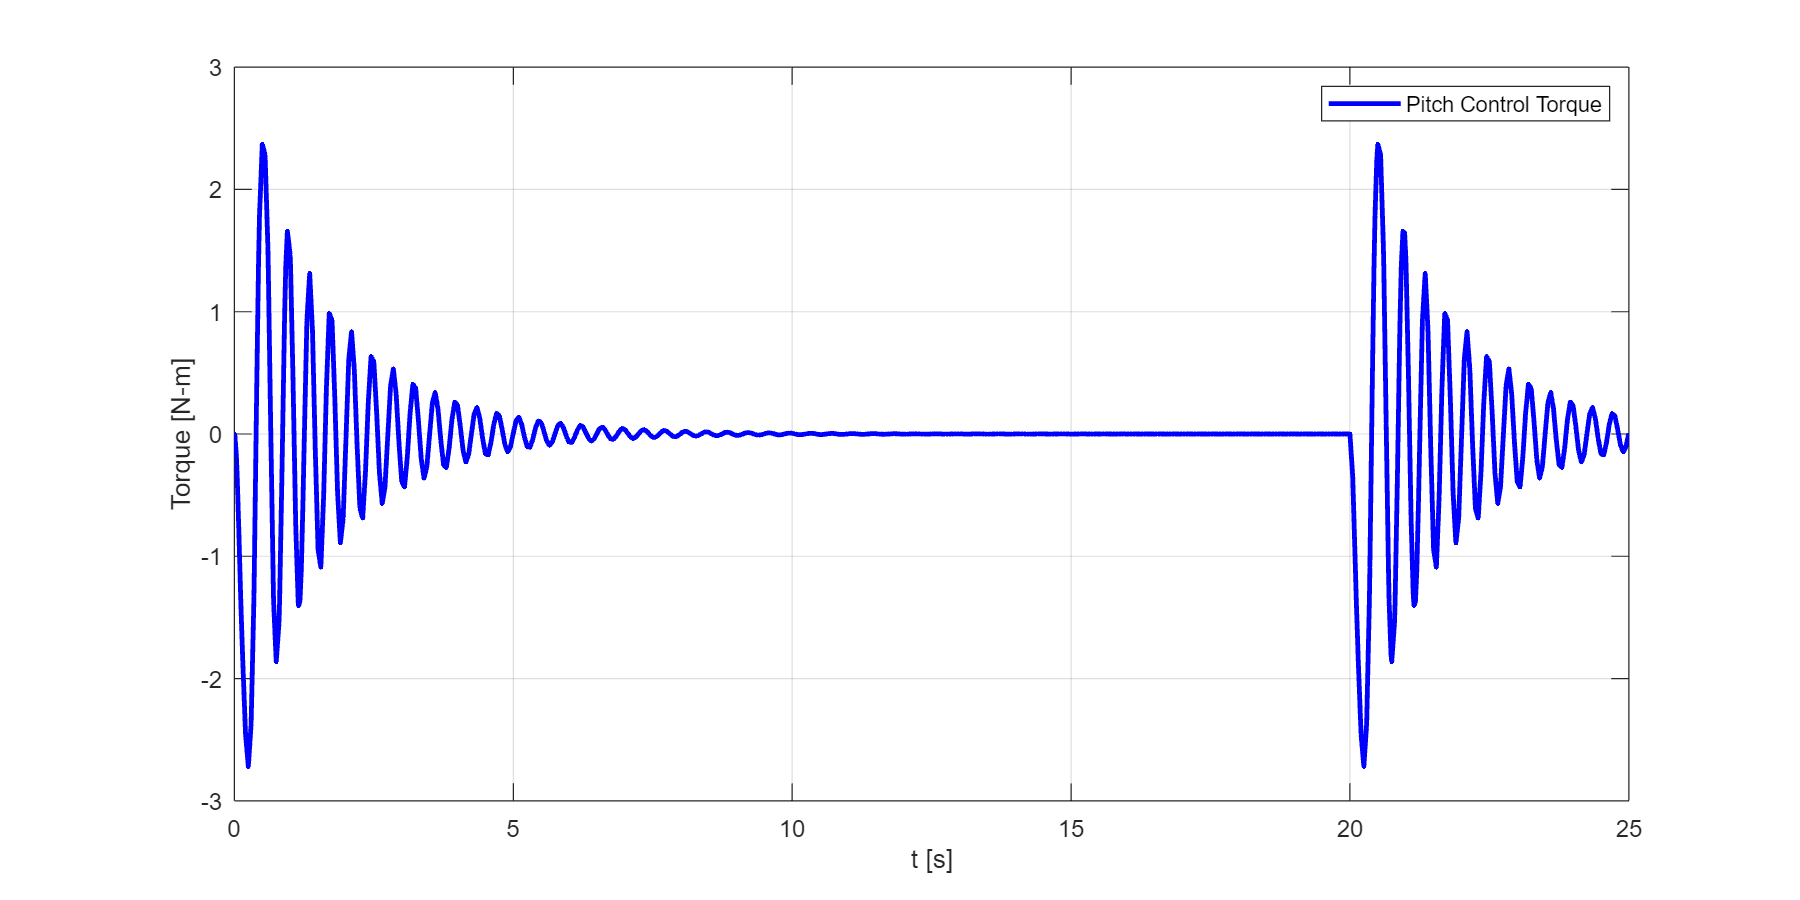

figure('Position',[0 0 1000 500]);
plot(t,simout.pitch_control,'b','LineWidth',2); grid on
ylabel('Torque [N-m]')
xlabel('t [s]')
legend('Pitch Control Torque')